# MLTWA Analysis

clear; clc; close all;

## 1. Input data

Add the original .mat file with the calculated energies for the 4 windows.

**DATA FORMAT REQUIRED:** The code expects a 5-column matrix of non-corrected energies:

- Col 1: Distances km

- Col 2: First Window energies

- Col 3: Second Window energies

- Col 4: Third Window energies

- Col 5: Coda Window energies (for normalization)

**However**, if your energies are **already corrected** for Geometrical Spreading, normalized by the coda, and in log10 scale, the code can handle this and avoid double corrections. You just need to set the data processing flag to TRUE (as explained later in the code). In this specific case, a 4-column matrix is sufficient (Col 1: Distances, Col 2-4: Processed Window energies).

**VARIABLE NAMING: **You don't necessarily need to rename the variables inside your .mat file. The script features a smart data loader: it will first look for the EXACT name you define in the 'labels' array below (e.g., if labels={'My_Freq_1_5'}, it looks for that specific variable). If the exact label isn't found, it uses the 'freqs' array to automatically guess standard MLTWA naming conventions (e.g., for 1.5 Hz, it will search for 'E1_5Hz', 'f1_5Hz', or 'Freq_1_5').

filename = 'MLTWA_Amatrice.mat'; 

if isfile(filename)
    raw_file = load(filename); 
    fprintf('File "%s" successfully loaded.\n', filename);
else
    error('File not found! Please check the name or path.');
end

File "MLTWA_Amatrice_corrected.mat" successfully loaded.


% --- Data Processing Flag ---
% Set to 'true' if your data is already normalized by coda, corrected for 
% geometrical spreading, and in log10 scale.
% Set to 'false' if your data is raw and needs this processing.

is_data_processed = true;
freqs = [1.5, 3, 6, 12];

% freqs = 1.5;

labels = {'f1_5Hz', 'f3Hz', 'f6Hz', 'f12Hz'};

% labels = {'f1_5Hz'};

data_ready = prepare_mltwa_data(raw_file, freqs, labels, is_data_processed);


--- Loading and Processing Energies ---
  -> f1_5Hz: Loaded (Data assumed as already processed).
  -> f3Hz: Loaded (Data assumed as already processed).
  -> f6Hz: Loaded (Data assumed as already processed).
  -> f12Hz: Loaded (Data assumed as already processed).


Now, add the physical parameters for the calculation, and the size of the grid where you will perform the grid-search.

% --- Physical Parameters ---
sim_params = struct();
sim_params.v = 3.5;              % S-wave velocity
sim_params.deltaT = 15;          % Time window length 
sim_params.Fs = 10;              % Sampling frequency
sim_params.t_coda = 50;          % Coda start time
sim_params.min_dist = 20;         % Minimum distance for analysis
sim_params.max_dist = 80;        % Maximum distance for analysis

% --- Parallel Computing Settings ---
% 'auto' = uses all available physical cores (maximum speed).
% 0      = disables parallelization (runs sequentially, NO toolbox required).
% N      = uses exactly N cores (e.g., set to 4 to keep your PC usable).
sim_params.num_workers = 'auto';

% --- Grid Search Settings ---
% Change here for the grid size (third variable in the linspace function.
% Here as an example is 10.
grid_settings = struct();
grid_settings.b0_vec = linspace(0.05, 0.95, 20); % B0 (Seismic Albedo) grid
grid_settings.le_vec = linspace(0.004, 0.12, 20); % Le^-1 (Extinction Length) grid
%grid_settings.b0_vec = 0.05:0.05:0.95; % Esattamente 19 punti come Akinci
%grid_settings.le_vec = 0.004:0.004:0.12; % Esattamente 30 punti come nel notebook

## 2. Data Check and example of B0 and Le-1 

Number of outliers removed (top/bottom 0.5%)


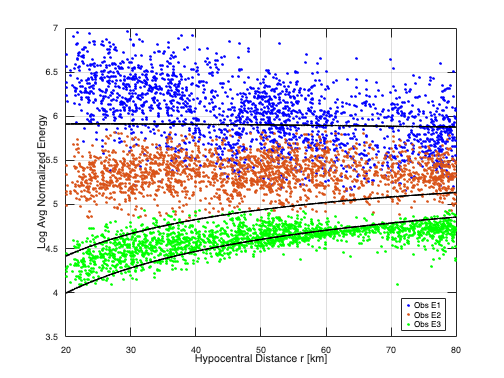

mse = 0.45085


if isfield(data_ready, 'f1_5Hz')
    d_check = data_ready.f1_5Hz;
    data_struct = struct('rn', d_check(:,1), 'E1', d_check(:,2), 'E2', d_check(:,3), 'E3', d_check(:,4));
    mse = analysis_one_point(0.7, 0.01, data_struct, sim_params);
    disp("mse = " + mse);
else
    warning('f1_5Hz data not available for check.');
end

## 3. Grid Search Run

final_results = run_MLTWA_automation(data_ready, sim_params, grid_settings, freqs, labels);

 -> Working on frequency: 1.5 Hz... -> Working on frequency: 3.0 Hz... -> Working on frequency: 6.0 Hz... -> Working on frequency: 12.0 Hz...


save('Final_Complete_Results_Amatrice.mat', 'final_results');

## 4. Results

Set to 'true' to use the centroid of multiple local minima (if present).Set to 'false' to strictly use the absolute minimum of the grid.

Summary figure saved as: Attenuation_Summary.png


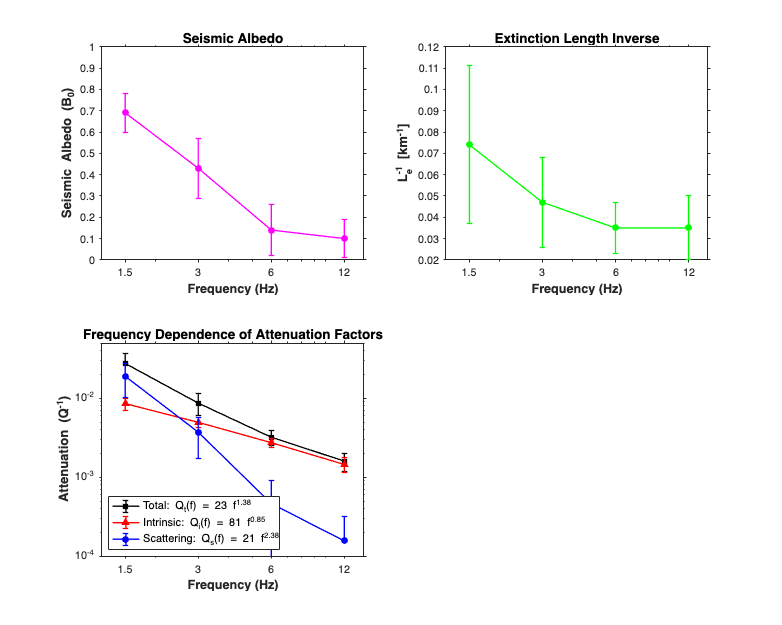

use_centroid = true;
use_smooth   = false; 

ResultsTable = extract_mltwa_results_table(final_results, freqs, labels, sim_params.v, use_centroid,use_smooth);

disp(ResultsTable);

    Freq_Hz        Le_inv              B0                 Qt_inv                   Qi_inv                   Qs_inv        
    _______    _______________    _____________    _____________________    _____________________    _____________________

      1.5      "0.074 ± 0.037"    "0.69 ± 0.09"    "2.76e-02 ± 9.66e-03"    "8.56e-03 ± 1.47e-03"    "1.90e-02 ± 8.70e-03"
        3      "0.047 ± 0.021"    "0.43 ± 0.14"    "8.68e-03 ± 2.69e-03"    "4.96e-03 ± 7.53e-04"    "3.72e-03 ± 1.97e-03"
        6      "0.035 ± 0.012"    "0.14 ± 0.12"    "3.21e-03 ± 6.92e-04"    "2.74e-03 ± 3.65e-04"    "4.64e-04 ± 4.57e-04"
       12      "0.035 ± 0.015"    "0.10 ± 0.09"    "1.60e-03 ± 4.25e-04"    "1.45e-03 ± 3.11e-04"    "1.56e-04 ± 1.60e-04"



writetable(ResultsTable, 'Final_Table_B0_Le.txt', 'Delimiter', '\t');